# Part 1

## Change of Variable

A core concept in finite elements is that of *change of variable.*  Immediately, we will use this concept to simplify numerical integration (quadrature), though later this will lead to the idea of *parent elements *and mapping to/from various configurations utilized within finite element implemntations, for example: *parametric*, *reference, current* configurations.

As a simple example of this, let us imagine that we have some function, $f\left(x\right)$, that we wish to integrate over the domain $\left\lbrack 2,7\right\rbrack$.  Let us further imagine that we have inherited some code that only supports integration over the domain $\left\lbrack -1,1\right\rbrack$. How can we proceed?

Let's imagine that we could define some function, $g\left(\xi \right)$, such that $f\left(x\right)=g\left(\xi \right)$.  That is, when we evaluate $g\left(\xi \right)$ at some value in the domain $\left\lbrack -1,1\right\rbrack$, it evaluates to its "equivalent" value in the function $f\left(x\right)$ in the domain $\left\lbrack 2,7\right\rbrack$.  By "equivalent" we mean that if we evaluate $g\left(\xi \right)$ at its left boundary, it should be equivalent to evaluating $f\left(x\right)$ at its left boundary: $f\left(2\right)\equiv g\left(-1\right)$. Similarly evaluating at the right boundaries should be equivalent, $f\left(7\right)\equiv g\left(1\right)$; evaluating each at their midpoint should be equivalent, $f\left(4\ldotp 5\right)\equiv g\left(0\right)$, etc.  

We can do this if we allow for $x$ to be a function (a *mapping*) that allows us to convert some value of $\xi$ into a value for $x$.  We can write this mapping as $x\left(\xi \right)$, and the inverse of this mapping as $\xi \left(x\right)$.  So how can we write a function that maps between the two domains?  Let's step through this logically:

- Scale one of the two domains so that they have the same range ("length")

- Shift the modified domain so that its lower bound equals the other

Let's choose to modify the domain of $\xi$ so that we determine $x\left(\xi \right)$.

- Shift $\left\lbrack -1,1\right\rbrack$ by $1$ to simplify scaling (since multiplying by zero is always zero): $\left\lbrack -1,1\right\rbrack \to \left\lbrack 0,2\right\rbrack$

- Multiply by $\left( \frac{7-2}{1 - ^{-}1}\right) = 2.5$ to make the domains have equal range: $\left\lbrack 0,\;2\right\rbrack \to \left\lbrack 0,5\right\rbrack$

- Shift $\left\lbrack 0,5\right\rbrack$ by $2$ so that they are now equivalent: $\left\lbrack 0,5\right\rbrack \to \left\lbrack 2,7\right\rbrack$

Ok, so that works!  But what are the equations behind this process?  If we generalize this concept now by replacing the numbers with variables, it will become clear:

- 
$$\left[ \xi_0, \xi_1 \right] - \xi_0$$


- 
$$\left( \left[ \xi_0, \xi_1 \right] - \xi_0 \right) \cdot \left( \frac{x_1 - x_0}{\xi_1 - \xi_0} \right)$$


- 
$$\left( \left[ \xi_0, \xi_1 \right] - \xi_0 \right) \cdot \left( \frac{x_1 - x_0}{\xi_1 - \xi_0} \right) + x_0$$


And, recognizing that $\left\lbrack \xi_0 ,\xi_1 \right\rbrack$ is a "stand-in" for the value of $\xi$ that we're evaluating, we can reformat a bit to recover the mappings:


$$x(\xi) = \left( \xi - \xi_0 \right) \cdot \left( \frac{x_1 - x_0}{\xi_1 - \xi_0} \right)$$



$$\xi(x) = \left( x - x_0 \right) \cdot \left( \frac{\xi_1 - \xi_0}{x_1 - x_0} \right)$$


Noting the similar structure of these two mappings, let's now write a function that simply maps *from* some domain *to* some other domain using change of variable.

function x = ChangeOfVariable( x, from_domain, to_domain )
x = x - from_domain(1);
x = x * ( ( to_domain(2) - to_domain(1) ) / ( from_domain(2) - from_domain(1) ) );
x = x + to_domain(1);
end

Let's see this function in action

clear
close all

to_values =     2.0000    3.2500    4.5000    5.7500    7.0000



from_domain = [-1, 1];
to_domain = [2, 7];

from_values = [-1, -0.5, 0, 0.5, 1];
to_values = ChangeOfVariable( from_values, from_domain, to_domain )

We can plot the values of `from_values` and `to_values`,  showing how they're connected to each other:

figure
hold on
for n = 1 : 5
    plot( [from_values(n) to_values(n)], [1 0], Color="k", LineWidth=1 )
end

ax = gca;
ax.YTick = [];
ax.XLim = [ min( [from_domain, to_domain] ) - 1,  max( [from_domain, to_domain] ) + 1 ];
ax.YLim = [-0.5, 1.5];
ax.XGrid = "on";

scatter( from_values, ones( 5, 1 ), Marker="s", MarkerFaceColor="flat", MarkerEdgeColor="k", SizeData=120, LineWidth=1, SeriesIndex=1 )
text( mean( from_domain ), 1.25, "$\xi$", Interpreter="latex", HorizontalAlignment="center", VerticalAlignment="middle" )

scatter( to_values, zeros( 5, 1 ), Marker="o", MarkerFaceColor="flat", MarkerEdgeColor="k", SizeData=120, LineWidth=1, SeriesIndex=2 )
text( mean( to_domain ), -0.25, "$x$", Interpreter="latex", HorizontalAlignment="center", VerticalAlignment="middle" )

scaled_arrow( ax, [mean( [from_domain(1), to_domain(1) ] ) - 1, 0.5], ( 1 - 0 ) / ( from_domain(1) - to_domain(1) ), 1 )
scaled_arrow( ax, [mean( [from_domain(end), to_domain(end)] ) + 1, 0.5], ( 1 - 0 ) / ( from_domain(end) - to_domain(end) ), -1 )
text( mean( [from_domain(1), to_domain(1) ] ) - 1.5, 0.5, "$x(\xi)$", Interpreter="latex", HorizontalAlignment="center", VerticalAlignment="middle" )
text( mean( [from_domain(end), to_domain(end)] ) + 1.5, 0.5, "$\xi(x)$", Interpreter="latex", HorizontalAlignment="center", VerticalAlignment="middle" )

Now let's see what happens when we use the change of variable in an actual function.  First let's choose a function defined over $x$ and map it to $\xi$:


$$f(x) = e^{x}\cos( \pi x ) \\ x \in [2, 7]$$


clear
close all

x = sym( "x", "real" );
from_domain = [2, 7];

$$xi(x) = \frac{5\,x}{2}+\frac{9}{2}$$

to_domain = [-1, 1];

$$g(x) = \cos\left(\pi \,\left(\frac{5\,x}{2}+\frac{9}{2}\right)\right)\,{\mathrm{e}}^{\frac{5\,x}{2}+\frac{9}{2}}$$

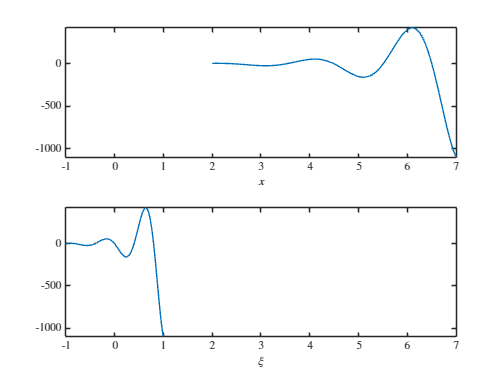

f(x) = exp( x ) * cos( pi * x );

xi(x) = ChangeOfVariable( x, to_domain, from_domain )
g = subs( f, x, xi )

figure
ax(1) = subplot( 2, 1, 1 );
fplot( f, from_domain )
ax(1).XLim = [min( [from_domain, to_domain] ), max( [from_domain, to_domain] )];
xlabel( "$x$", Interpreter="latex" )


ax(2) = subplot( 2, 1, 2 );
fplot( g, to_domain )
ax(2).XLim = [min( [from_domain, to_domain] ), max( [from_domain, to_domain] )];
xlabel( "$\xi$", Interpreter="latex" )

And again on another function, this time mapping from $\xi$ to $x$:


$$f(\xi) = \Re(\xi^\xi) \\ \xi \in [-1, 1]$$


clear

xi = sym( "xi", "real" );
from_domain = [-1, 1];
to_domain = [2, 7];
f(xi) = real( xi^xi );

$$x(xi) = \frac{2\,\xi }{5}-\frac{9}{5}$$

$$g(xi) = \mathrm{real}\left({\left(\frac{2\,\xi }{5}-\frac{9}{5}\right)}^{\frac{2\,\xi }{5}-\frac{9}{5}}\right)$$

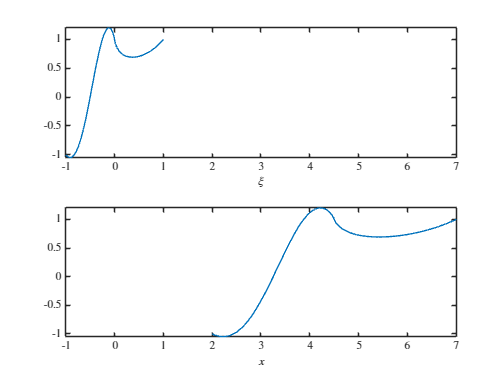

x(xi) = ChangeOfVariable( xi, to_domain, from_domain )
g = subs( f, xi, x )

figure
ax(1) = subplot( 2, 1, 1 );
fplot( f, from_domain )
ax(1).XLim = [min( [from_domain, to_domain] ), max( [from_domain, to_domain] )];
xlabel( "$\xi$", Interpreter="latex" )

ax(2) = subplot( 2, 1, 2 );
fplot( g, to_domain )

ax(2).XLim = [min( [from_domain, to_domain] ), max( [from_domain, to_domain] )];
xlabel( "$x$", Interpreter="latex" )

## Polynomial Roots from Linear Algebra

A common problem in mathematics is finding the roots (zeros) of a function.  As we will see shortly, we will want to find roots of polynomial functions to aid us in constructing polynomial basis and quadrature schemes.  A common approach to finding roots of functions is to use bracketing methods (e.g., bisection method) or iterative methods based on derivatives (e.g., secant method, Newton's method).  However these methods face many challenges such as how to choose a reasonable starting location, initial bracket bounds, avoiding stagnation, finding multiple roots, duplicate roots, etc.  So how might we avoid these challenges with polynomials?

You may recall from your early linear algebra courses the idea of the *characteristic polynomial* for a matrix.  In short, any square matrix has a characteristic polynomial whose roots are the eigenvalues of the matrix.  So what we want to do is to construct a matrix whose characteristic polynomial is the polynomial we want to find the roots of, and then compute the eigenvalues.  For any characteristic polynomial, there are an infinite number of matrices that share the characteristic polynomial (i.e., matrix similarity), however one approach results in constructing what is called the *companion matrix*.

The companion matrix is defined for a *monic polynomial, *$p\left(x\right)=c_0 x^0 +c_1 x^1 +\cdots +c_{n-1} x^{n-1} +c_n x^n$, as:


$$C=\left\lbrack \begin{array}{ccccc}
0 & 0 & \cdots \; & 0 & -c_0 \\
1 & 0 & \cdots  & 0 & -c_1 \\
0 & 1 & \cdots  & 0 & -c_2 \\
\vdots  & \vdots  & \ddots  & \vdots  & \vdots \;\\
0 & 0 & \cdots  & 1 & -c_{n-1} 
\end{array}\right\rbrack$$


Recall that for a given polynomial we can convert it to a monic polynomial by simply dividing by the leading coefficient.  Let's work through an example:

clear
x = sym( "x" );
polynomial = x^6 - (3/2)*x^5 - 5*x^4 + (15/2)*x^3 + 4*x^2 - 6*x

$$polynomial = x^{6}-\frac{3\,x^{5}}{2}-5\,x^{4}+\frac{15\,x^{3}}{2}+4\,x^{2}-6\,x$$

c = coeffs( polynomial, "All" )

$$c = \left[\begin{array}{ccccccc} 1 & -\frac{3}{2} & -5 & \frac{15}{2} & 4 & -6 & 0 \end{array}\right]$$


monic_polynomial = polynomial / c(1)

$$monic\_polynomial = x^{6}-\frac{3\,x^{5}}{2}-5\,x^{4}+\frac{15\,x^{3}}{2}+4\,x^{2}-6\,x$$

monic_c = coeffs( monic_polynomial, "All" )

$$monic\_c = \left[\begin{array}{ccccccc} 1 & -\frac{3}{2} & -5 & \frac{15}{2} & 4 & -6 & 0 \end{array}\right]$$

Let's write a routine that computes the companion matrix:

function C = CompanionMatrix( polynomial )

$$C = \left[\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 6\\ 0 & 1 & 0 & 0 & 0 & -4\\ 0 & 0 & 1 & 0 & 0 & -\frac{15}{2}\\ 0 & 0 & 0 & 1 & 0 & 5\\ 0 & 0 & 0 & 0 & 1 & \frac{3}{2} \end{array}\right]$$

c = coeffs( polynomial, "All" );
monic_polynomial = poly2sym( c / c(1) ); % Create the monic polynomial

$$polynomial\_roots = \left[\begin{array}{c} -2\\ -1\\ 0\\ 1\\ \frac{3}{2}\\ 2 \end{array}\right]$$

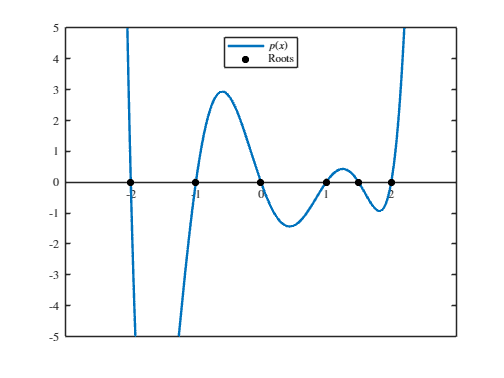

c = fliplr( coeffs( monic_polynomial, "All" ) );
if length( c ) > 2
    C = sym( zeros( length(c) - 1 ) );
    C(2:end, 1:end-1) = eye( length(c) - 2 );
    C(:, end) = - ( c( 1:end-1 ) ./ c(end) );
elseif length( c ) == 2
    % Handle case when polynomial is a linear, C is a [1x1] matrix
    C =  c(1) / (-c(2)) ;
elseif isscalar( c )
    % Handle case when polynomial is a constant

    C = [];
end
end

Thus the companion matrix is:

C = CompanionMatrix( polynomial )

$$r = \left[\begin{array}{c} -2\\ -1\\ 0\\ 1\\ \frac{3}{2}\\ 2 \end{array}\right]$$

Next we compute the eigenvalues of this matrix to recover the roots:

polynomial_roots = eig( C )

And now we can plot the polynomial and its roots to visually confirm that this approach has, in fact, found the polynomial's roots.

figure
hold on
fplot( polynomial, [-3 3], LineWidth=2, DisplayName="$$p(x)$$" )
scatter( double( polynomial_roots ), zeros( size( double( polynomial_roots ) ) ), MarkerFaceColor="k", MarkerEdgeColor="none", DisplayName="Roots" )
legend( Location="north" )

ax = gca;
ax.YLim = [-5 5];
ax.XAxisLocation = "origin";

Matlab's `eig` function returns unsorted eigenvalues and it may (will) be desirable to sort the eigenvalues from low-to-high.  Furthermore, we will want an easy way to automatically return the roots, so lets write a function that performs this for us.

function poly_roots = PolynomialRoots( polynomial )

$$monomial\_basis = \left[\begin{array}{c} 1\\ x\\ x^{2}\\ x^{3}\\ x^{4} \end{array}\right]$$

C = CompanionMatrix( polynomial );
poly_roots = eig( C );

$$monomial\_basis = \left[\begin{array}{c} 1\\ \frac{x}{2}+\frac{1}{2}\\ \frac{{\left(x+1\right)}^{2}}{4}\\ \frac{{\left(x+1\right)}^{3}}{8}\\ \frac{{\left(x+1\right)}^{4}}{16} \end{array}\right]$$

[~, sidx] = sort( double ( real( vpa( poly_roots ) ) ) );
poly_roots = poly_roots( sidx );
poly_roots = simplify( poly_roots, Steps=100, Seconds=1 );
end

And double-check our work:

r = PolynomialRoots( polynomial )

Finally, let's take a moment to make a quick observation and comment.  You may be aware that there are no closed-form equations, using only elementary arithmetic operations and fractional powers, for computing the roots of polynomials *greater *than degree-4 -- this is the Abel-Ruffini theorem.  Of course, for some polynomials of degree greater than four *we can* write such equations, such as $p\left(x\right)=x^{100} -1$, but not in the general case.  Consider that, *if* there existed an algorithm for computing exact eigenvalues in a finite number of steps for matrices of size $5\times 5$ (corresponding to quintics) or larger, that then we would have an equation for finding roots of polynomials greater than degree-4.  This is why, in practical finite element codes, eigenvalue extraction methods are all approximate iterative methods (e.g., power method, Arnoldi method, Lancoz method, QR algorithm, LOBPCG).

## Polynomial Bases

What *is* a polynomial?  Chances are that you have a pretty good basic understanding of polynomials, you know a polynomial when you see it.  But you may not have considered polynomials as being a vector space, of each polynomial function being describable as a linear combination of coefficients and a polynomial basis.  Let's investigate.

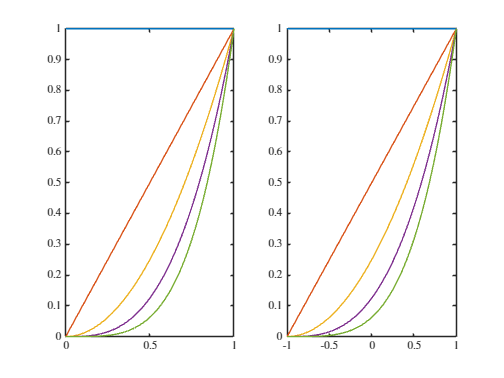

clear

close all
degree = 4;
x = sym("x");

### The monomial basis

The polynomial basis probably most readily understood is the *monomial basis*, sometimes called the *power basis.*

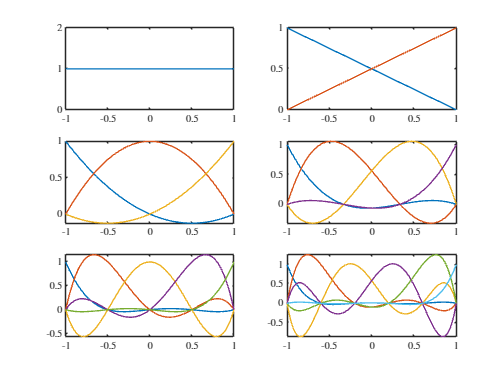

function bFun = MonomialBasis( degree, variate, domain )
variate = ChangeOfVariable( variate, domain, [0, 1] );
bFun = sym( zeros( degree + 1, 1 ) );
for ii = 1 : degree + 1
    bFun(ii) = variate ^ (ii-1);

end
bFun = simplify( bFun );
end

These basis polynomials are, as the name suggests, the familiar monomials and, as such, is normally defined over the unit domain $\left\lbrack 0,1\right\rbrack$

monomial_basis = MonomialBasis( degree, x, [0, 1] )

However, including the change of basis operator in its construction allows for defining the monomial basis over any domain, such as the bi-unit domain$\left\lbrack -1,1\right\rbrack$:

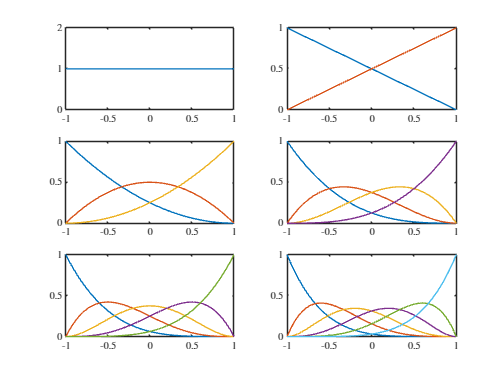

monomial_basis = MonomialBasis( degree, x, [-1, 1] )

Plotting the basis over the two domains

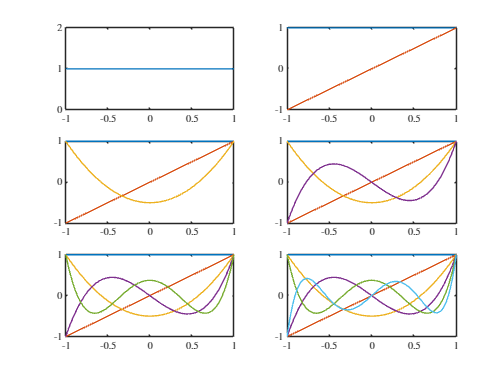

figure
subplot( 1, 2, 1 )
fplot( MonomialBasis( degree, x, [0, 1] ), [0, 1] )
subplot( 1, 2, 2 )
fplot( MonomialBasis( degree, x, [-1, 1] ), [-1, 1] )

### The Lagrange basis

The Lagrange basis is a so-called *interpolatory basis* and has wide applications in interpolation and approximation.  In fact, because of its interpolation properties it is the *de facto* standard basis used in traditional finite element codes.  It also gives rise to the Lagrange interpolating polynomial.

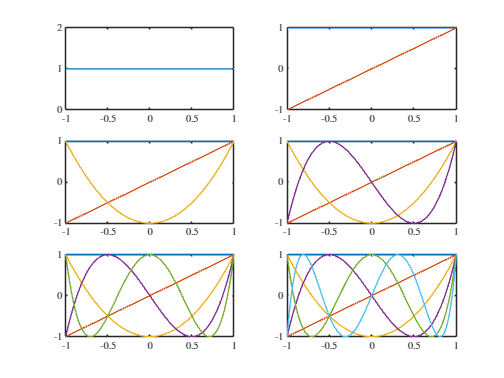

function bFun = LagrangeBasis( degree, variate, domain )
node = linspace( domain(1), domain(2), degree + 1 );
bFun = sym( zeros( degree+1, 1 ) );
for ii=1:degree+1  % ii is the current nodal basis function we're building
    bFun(ii) = variate ^ 0;

    for jj = 1 : degree + 1 % jj is evaluating the product series for the current node
        if ii ~= jj
            bFun(ii) = bFun(ii) * ( ( variate - node(jj) ) / ( node(ii) - node(jj) ) );
        end
    end
end
bFun = simplify( bFun );
end

Note that the Lagrange basis is usually defined over the bi-unit domain $\left\lbrack -1,1\right\rbrack$

figure
for degree = 0 : 5
    subplot( 3, 2, degree + 1 )
    fplot( LagrangeBasis( degree, x, [-1, 1] ), [-1, 1] )
end

### The Bernstein basis

The Bernstein basis is both a historically significant basis and currently a vital basis in the fields of approximation, computer-aided design, computer graphics, and even computer font design.  It forms the foundation for such things as Bezier curves, B-splines, NURBS, and isogeometric analysis.  We will talk more about these later.

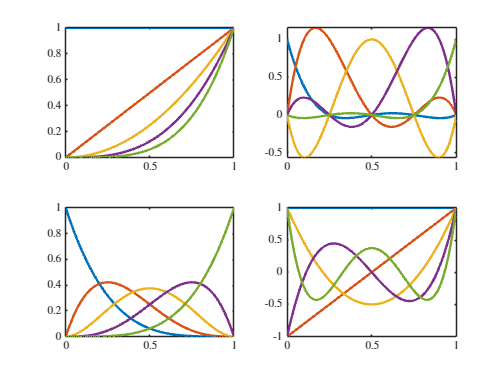

function bFun = BernsteinBasis( degree, variate, domain )
variate = ChangeOfVariable( variate, domain, [0 1] );
bFun = sym( zeros( degree + 1, 1 ) );
for a=0:degree
    bFun(a+1) = nchoosek( degree, a ) * ( variate ^ a ) * ( ( 1 - variate ) ^ ( degree - a ) );
end
bFun = simplify( bFun );

end

Note that the Bernstein basis is usually defined over the unit domain $\left\lbrack 0,1\right\rbrack$

figure
for degree = 0 : 5
    subplot( 3, 2, degree + 1 )
    fplot( BernsteinBasis( degree, x, [-1, 1] ), [-1, 1] )
end

### The Legendre basis

The Legendre basis is the first of the *orthogonal basis,* so-called each basis polynomial is orthogonal in the $L^2$-norm to every other polynomial in the basis -- we'll define what this means later.  For now, it's enough to know that this orthogonality property provides a number of desirable numerical properties, even at high polynomial degree (especially in contrast to the Lagrange basis), and will prove especially useful when we later develop numerical quadrature based on the Legendre basis.

function bFun = LegendreBasis( degree, variate, domain )
variate = ChangeOfVariable( variate, domain, [-1, 1] );

$$f = \sin\left(x\right)$$

bFun = sym( zeros( degree + 1, 1 ) );

$$g = \sin\left(x\right)$$

for ii = 0 : degree
    if ii == 0

$$L2\_ff = \pi$$

        bFun(ii+1) = variate ^ 0 ;

$$L2\_fg = \pi$$

    elseif ii == 1
        bFun(ii+1) = variate ^ 1;
    else
        n = ii - 1;
        term1 = ( 2 * n + 1 ) * variate * bFun(n+1);
        term2 = n * bFun(n);
        bFun(ii+1) = simplify ( ( term1 - term2 ) / ( n + 1 ) );
    end
end
bFun = simplify( bFun );
end

Note that the Legendre basis is normally defined on the bi-unit domain $\left\lbrack -1,1\right\rbrack$.

figure
for degree = 0 : 5
    subplot( 3, 2, degree + 1 )
    fplot( LegendreBasis( degree, x, [-1, 1] ), [-1, 1] )
end

### The Chebyshev basis

The Chebyshev basis is another orthogonal basis, however its orthogonality is defined slighlty differently than the Legendre basis.  We will discuss this nuance later, but it is sufficient to say that it too has many beneficial numerical properties stemming from its orthogonality and is incredibly important in modern approximation theory.  Due to various transliterations of its namesake, Pafnuty Chebyshev, it is sometimes written as *Tchebycheff*, *Tchebyshev* (French), or *Tschebyschow* (German).

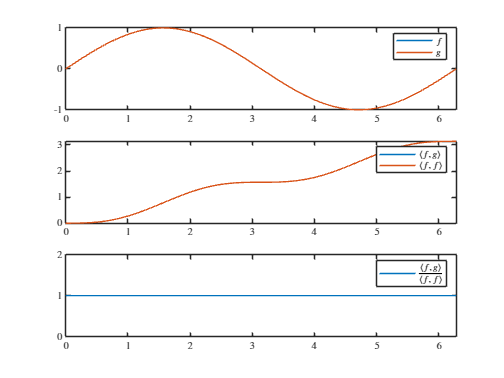

function bFun = ChebyshevBasis( degree, variate, domain )
variate = ChangeOfVariable( variate, domain, [-1, 1] );
bFun = sym( zeros( degree + 1, 1 ) );
for ii = 0 : degree
    if ii == 0
        bFun(ii+1) = variate ^ 0;
    elseif ii == 1

        bFun(ii+1) = variate ^ 1;
    else
        bFun(ii+1) = ( 2 * variate * bFun(ii) ) - bFun(ii-1);
    end
end

$$f = \sin\left(x\right)$$

bFun = simplify( bFun );

$$g = -\sin\left(x\right)$$

end

Note that the Legendre basis is normally defined on the bi-unit domain $\left\lbrack -1,1\right\rbrack$.

figure

$$L2\_ff = \pi$$

for degree = 0 : 5

$$L2\_fg = -\pi$$

    subplot( 3, 2, degree + 1 )
    fplot( ChebyshevBasis( degree, x, [-1, 1] ), [-1, 1] )
end

### Other basis polynomials

There are a multitude of other basis polynomials which we will not show here, but these include modifications of the Lagrange basis, where roots of the Legendre and Chebyshev basis can be used as the nodes (roots) of the Lagrange basis, thus modifying the Lagrange basis slightly.  The resulting basis, while perhaps not as commonly used as the aforementioned basis, inherit some of the beneficial numerical properties of their orthogonal progenitors -- such as minimizing the deleterious Runge phenomenon observed at higher-orders.  Also included are various other orthogonal polynomials such as the Leguerre, Lobatto, Hermite, and Jacobi polynomials, to name a few.

To simplify accessing the various basis polynomials, let's define an interface function:

function basisFun = PolynomialBasisFunction( basisName, degree, variate, domain )
switch basisName
    case "Bernstein"
        basisFun = BernsteinBasis( degree, variate, domain );
    case "Chebyshev"
        basisFun = ChebyshevBasis( degree, variate, domain );
    case "Lagrange"
        basisFun = LagrangeBasis( degree, variate, domain );
    case "Lagrange-Chebyshev"
        basisFun = LagrangeChebyshevBasis( degree, variate, domain );
    case "Lagrange-Legendre"
        basisFun = LagrangeLegendreBasis( degree, variate, domain );
    case "Legendre"
        basisFun = LegendreBasis( degree, variate, domain );
    case "Monomial"
        basisFun = MonomialBasis( degree, variate, domain );
end
end

Let's compare the common basis functions against each other

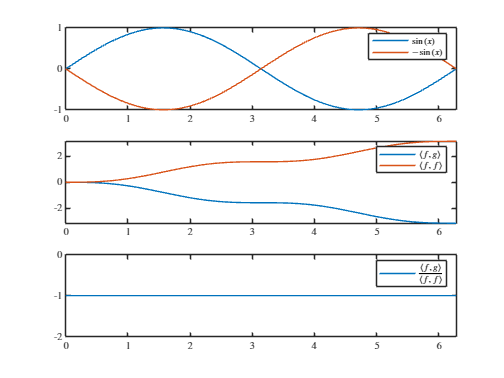

degree = 4;
domain = [0, 1];


figure
subplot( 2, 2, 1 )

$$f = \sin\left(x\right)$$

fplot( PolynomialBasisFunction( "Monomial", degree, x, domain ), domain, LineWidth=2 );

$$g = \cos\left(x\right)$$

subplot( 2, 2, 2 )
fplot( PolynomialBasisFunction( "Lagrange", degree, x, domain ), domain, LineWidth=2 );
subplot( 2, 2, 3 )

$$L2\_ff = \frac{x}{2}-\frac{\sin\left(2\,x\right)}{4}$$

fplot( PolynomialBasisFunction( "Bernstein", degree, x, domain ), domain, LineWidth=2 );

$$L2\_fg = \frac{{\sin\left(x\right)}^{2}}{2}$$

subplot( 2, 2, 4 )
fplot( PolynomialBasisFunction( "Legendre", degree, x, domain ), domain, LineWidth=2 );

## Inner Products

Just as measuring quanitities is critical in engineering and science, so to is it important in mathematics.  For example, when working with vectors one often wishes to know "how similar are these two vectors?" -- a question that every STEM practitioner knows to solve via the *dot product.*  It is perhaps unfortunate, however, that far fewer STEM practioners understand the dot product as an *inner product.* 

The inner product of the $L^2$ vector space (function space) is known as the $L^2$ inner product and is defined as:


$$\langle \;f,g\;\rangle =\int_{\Omega } f\;g\;d\Omega$$


And the norm induced by the $L^2$ inner product is the $L^2$-norm:


$$\left\| f \right\| = \sqrt{\langle f, f \rangle}$$


Using the $L^2$ inner product we can compare how close two functions in the $L^2$ function space are to each other. 

- $\left\langle f,g\right\rangle =\left\langle f,f\right\rangle$ -- tells us that $f$ and $g$ are equivalent ($f=g$)

- $\left\langle f,g\right\rangle =-\left\langle f,f\right\rangle$  -- tells us that $f$ and $g$ are additive inverses of each other ($f=-g$)

- $\left\langle f,g\right\rangle =0$ -- tells us that $f$ and $g$ are orthogonal (perpindicular) to each other ($f\bot g$)

Let's consider some examples

- 
$$f=\sin \left(x\right);\;\;g=\sin \left(x\right)$$


- 
$$f=\sin \left(x\right);\;\;g=-\sin \left(x\right)$$


- 
$$f=\sin \left(x\right);\;\;g=\cos \left(x\right)$$


- 
$$f=\sin \left(\pi \;x\right);\;g=-{\left(2x-1\right)}^{2\;} +1$$


clear

x_equiv = 1.2060

close all

x_orth = 3.1416

x = sym( "x", "real" );

### Case 1: $f=\sin \left(x\right);\;\;g=\sin \left(x\right)$

Notice that in this case that $f$ and $g$ are equivalent.  This may seem obvious, but note that we can confirm this in the third subplot where $\frac{\left\langle f,g\right\rangle }{\left\langle f,f\right\rangle }=1$ over the whole domain.

domain = [0, 2*pi];
f = sin( x )
g = sin( x )

L2_ff = int( f*f, domain )
L2_fg = int( f*g, domain )

figure
subplot( 3, 1, 1 )
hold on
fplot( f, domain, DisplayName="$f$" )
fplot( g, domain, DisplayName="$g$" )
legend
ax = gca;
ax.XLim = domain;

subplot( 3, 1, 2 )
hold on
fplot( int( f*g, [0 x] ), domain, DisplayName="$\langle f, g \rangle$" )
fplot( int( f*f, [0 x] ), domain, DisplayName="$\langle f, f \rangle$" )
legend
ax = gca;
ax.XLim = domain;

subplot( 3, 1, 3 )
fplot( int( f*g, [0 x] ) / int( f*f, [0 x] ), domain, DisplayName="$\frac{ \langle f, g \rangle }{ \langle f, f \rangle }$" )
legend
ax = gca;
ax.XLim = domain;

### Case 2: $f=\sin \left(x\right);\;\;g=-\sin \left(x\right)$

Notice that in this case that $f$ and $g$ are "equal, but opposite."  Again, this may seem obvious, but we confirm this in the third subplot where $\frac{\left\langle f,g\right\rangle }{\left\langle f,f\right\rangle }=-1$ over the whole domain.

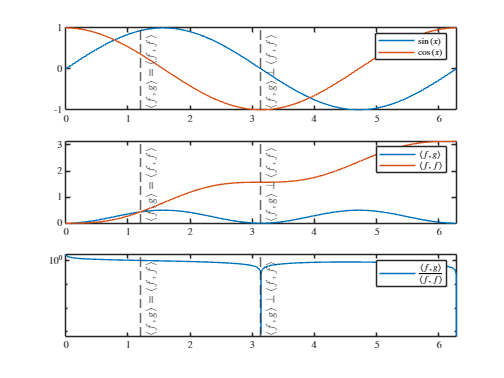

x = sym( "x", "real" );

domain = [0, 2*pi];
f = sin( x )
g = -sin( x )

$$f = \sin\left(\pi \,x\right)$$

$$g = 1-{\left(2\,x-1\right)}^{2}$$

L2_ff = int( f*f, domain )
L2_fg = int( f*g, domain )


$$L2\_ff = 1$$

figure

$$L2\_fg = \frac{8}{\pi }$$

subplot( 3, 1, 1 )
hold on
fplot( f, domain, DisplayName="$"+latex(f)+"$" )
fplot( g, domain, DisplayName="$"+latex(g)+"$" )
legend
ax = gca;
ax.XLim = domain;

subplot( 3, 1, 2 )
hold on
fplot( int( f*g, [0 x] ), domain, DisplayName="$\langle f, g \rangle$" )
fplot( int( f*f, [0 x] ), domain, DisplayName="$\langle f, f \rangle$" )
legend
ax = gca;
ax.XLim = domain;

subplot( 3, 1, 3 )
fplot( int( f*g, [0 x] ) / int( f*f, [0 x] ), domain, DisplayName="$\frac{ \langle f, g \rangle }{ \langle f, f \rangle }$" )
legend
ax = gca;

$$ans = \frac{8}{\pi^{3}}-\frac{8\,\cos\left(\pi \,x\right)}{\pi^{3}}-\frac{\cos\left(\pi \,x\right)}{\pi }+\frac{\cos\left(\pi \,x\right)\,{\left(2\,x-1\right)}^{2}}{\pi }-\frac{4\,\sin\left(\pi \,x\right)\,\left(2\,x-1\right)}{\pi^{2}}$$

ax.XLim = domain;

$$ans = \frac{x}{2}-\frac{\sin\left(2\,\pi \,x\right)}{4\,\pi }$$

### Case 3: $f=\sin \left(x\right);\;\;g=\cos \left(x\right)$

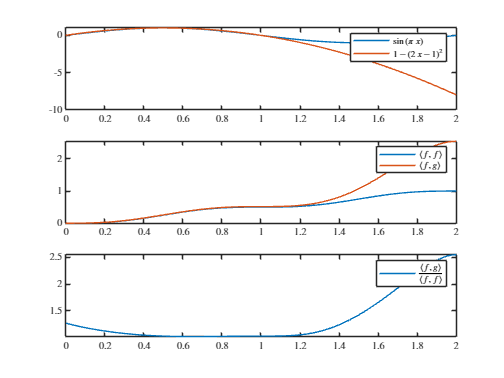

f = sin( x )
g = cos( x )
domain = [0, 2*pi];


L2_ff = int( f*f )
L2_fg = int( f*g )

L2_ratio = sqrt( int( f*g, [0 x] ) ) / sqrt( int( f*f, [0 x] ) );
x_equiv = double( solve( L2_ratio == 1 ) )
x_orth = double( solve( L2_ratio == 0 ) )

figure
subplot( 3, 1, 1 )
hold on
fplot( f, domain, DisplayName="$"+latex(f)+"$" )
fplot( g, domain, DisplayName="$"+latex(g)+"$" )
xline( x_equiv, "--", "$\langle f, g \rangle = \langle f, f \rangle$", HandleVisibility="off" )
xline( x_orth, "--", "$\langle f, g \rangle \perp \langle f, f \rangle$", HandleVisibility="off" )
legend
ax = gca;
ax.XLim = domain;

subplot( 3, 1, 2 )
hold on
fplot( int( f*g, [0 x] ), domain, DisplayName="$\langle f, g \rangle$" )
fplot( int( f*f, [0 x] ), domain, DisplayName="$\langle f, f \rangle$" )
xline( x_equiv, "--", "$\langle f, g \rangle = \langle f, f \rangle$", HandleVisibility="off" )
xline( x_orth, "--", "$\langle f, g \rangle \perp \langle f, f \rangle$", HandleVisibility="off" )
legend
ax = gca;
ax.XLim = domain;

subplot( 3, 1, 3 )
% fplot( int( f*g, [0 x] ) / int( f*f, [0 x] ), domain, DisplayName="$\frac{ \langle f, g \rangle }{ \langle f, f \rangle }$" )
fplot( L2_ratio, domain, DisplayName="$\frac{ \langle f, g \rangle }{ \langle f, f \rangle }$" )
xline( x_equiv, "--", "$\langle f, g \rangle = \langle f, f \rangle$", HandleVisibility="off" )

$$E = \left[\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right]$$

xline( x_orth, "--", "$\langle f, g \rangle \perp \langle f, f \rangle$", HandleVisibility="off" )

$$G = \left[\begin{array}{cc} 0 & 1\\ 1 & 0 \end{array}\right]$$

legend
ax = gca;

$$M = \left[\begin{array}{cc} \sin\left(\frac{37\,\pi }{600}\right) & \sin\left(\frac{263\,\pi }{600}\right)\\ \cos\left(\frac{37\,\pi }{600}\right) & -\cos\left(\frac{263\,\pi }{600}\right) \end{array}\right]$$

ax.XLim = domain;

ans =     0.1925    0.9813
    0.9813   -0.1925


ax.YScale = "log";

### Case 4: $f=\sin \left(\pi \;x\right);\;g=-{\left(2x-1\right)}^{2\;} +1$

f = sin( pi*x )
g = -(2*x-1)^2 + 1

$$m = \left[\begin{array}{c} \cos\left(\frac{7\,\pi }{1800}\right)\\ \sin\left(\frac{7\,\pi }{1800}\right) \end{array}\right]$$

domain = [0, 2];

L2_ff = int( f*f, domain )
L2_fg = int( f*g, domain )

figure
subplot( 3, 1, 1 )
hold on

$$D = \left[\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right]$$

fplot( f, domain, DisplayName="$"+latex(f)+"$" )

$$C = \left[\begin{array}{cc} \cos\left(\frac{37\,\pi }{600}\right) & -\cos\left(\frac{263\,\pi }{600}\right)\\ \sin\left(\frac{37\,\pi }{600}\right) & \sin\left(\frac{263\,\pi }{600}\right) \end{array}\right]$$

fplot( g, domain, DisplayName="$"+latex(g)+"$" )
legend

$$T\_MG = \left[\begin{array}{cc} \cos\left(\frac{37\,\pi }{600}\right) & -\cos\left(\frac{263\,\pi }{600}\right)\\ \sin\left(\frac{37\,\pi }{600}\right) & \sin\left(\frac{263\,\pi }{600}\right) \end{array}\right]$$

ax = gca;
ax.XLim = domain;

$$runway\_vector = \left[\begin{array}{c} \cos\left(\frac{37\,\pi }{600}\right)\,\cos\left(\frac{7\,\pi }{1800}\right)-\cos\left(\frac{263\,\pi }{600}\right)\,\sin\left(\frac{7\,\pi }{1800}\right)\\ \cos\left(\frac{7\,\pi }{1800}\right)\,\sin\left(\frac{37\,\pi }{600}\right)+\sin\left(\frac{263\,\pi }{600}\right)\,\sin\left(\frac{7\,\pi }{1800}\right) \end{array}\right]$$

runway_vector =     0.9789
    0.2045


subplot( 3, 1, 2 )

runway_orientation = 11.8000

hold on
fplot( int( f*f, [0 x] ), domain, DisplayName="$\langle f, f \rangle$" )
fplot( int( f*g, [0 x] ), domain, DisplayName="$\langle f, g \rangle$" )
legend
ax = gca;
ax.XLim = domain;

subplot( 3, 1, 3 )
int( f*g, [0 x] )
int( f*f, [0 x] )
fplot( int( f*g, [0 x] ) / int( f*f, [0 x]), domain, DisplayName="$\frac{ \langle f, g \rangle }{ \langle f, f \rangle }$" )
legend
ax = gca;
ax.XLim = domain;

## Change of Basis

We previously presented various different basis polynomials.  

Recall that an object within a given vector space is represented as a linear combination of basis vectors:


$$u=\sum_A^n c_A N_A =c_1 N_1 +c_2 N_2 +\cdots c_{n-1} N_{n-1} +c_n N_n$$


Sometimes, however, we may wish to represent this same object, exactly, in another basis:


$$u=v=\sum_B^n d_B M_B =d_1 M_1 +d_2 M+\cdots d_{n-1} M_{n-1} +d_n M_n$$


Leveraging the properties of the inner product we can solve for $d_B$, the unknown coefficients in this other basis:


$$\left\langle M_A ,v\right\rangle =\left\langle M_A ,u\right\rangle$$



$$\left\langle M_A ,\sum_B^n d_B M_B \right\rangle =\left\langle M_A ,\sum_B^n c_B N_B \right\rangle$$



$$\sum_{A,B}^n d_B \left\langle M_A ,M_B \right\rangle =\sum_{A,B}^n c_B \left\langle M_A ,N_B \right\rangle$$


Which we can write in matrix-vector format as:


$$\left\lbrack \begin{array}{ccc}
\left\langle M_1 ,M_1 \right\rangle  & \cdots  & \left\langle M_1 ,M_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle M_n ,M_1 \right\rangle  & \cdots  & \left\langle M_n ,M_n \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d_1 \\
\vdots \\
d_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\left\langle M_1 ,N_1 \right\rangle  & \cdots  & \left\langle M_1 ,N_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle M_n ,N_1 \right\rangle  & \cdots  & \left\langle M_n ,N_n \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_1 \\
\vdots \\
c_n 
\end{array}\right\rbrack$$


Or, more compactly, as:


$$\textrm{Dd}=\textrm{Cc}$$



$$\mathit{\mathbf{d}}={\left(\mathit{\mathbf{D}}\right)}^{-1} \textrm{Cc}$$


Note that since the matrix-vector product $\mathit{\mathbf{b}}=\textrm{Cc}$ is a vector we can recognize this as a linear system of equations: $\textrm{Dd}=\textrm{Cc}$ can be written as $\textrm{Ax}=\mathit{\mathbf{b}}$, or as $\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{-1} \mathit{\mathbf{b}}$, or $\mathit{\mathbf{d}}={\mathit{\mathbf{D}}}^{-1} \textrm{Cc}$.  Alternatively, we can evaluate the matrix-matrix product ${\mathit{\mathbf{R}}}_{\mathit{\mathbf{C}}\to \mathit{\mathbf{D}}} =\left({\mathit{\mathbf{D}}}^{-1} \right)\mathit{\mathbf{C}}$, which we call the *change of basis operator*, that we can store for reuse on multiple changes of basis: $\mathit{\mathbf{d}}={\mathit{\mathbf{R}}}_{\mathit{\mathbf{C}}\to \mathit{\mathbf{D}}} \mathit{\mathbf{c}}$.

#### A useful mnemonic device

The mixing of different bases can be a bit confusing, so let's introduce a mnemonic that may help with remembering how to construct the change of basis system.  Recall that we want to change ***F***rom one basis ***T***o another.  Then we represent the above matrix-vector system in condensed form i.e., the  mnemonic device that we can more easily remember:


$$\left\langle T,T\right\rangle \mathrm{t}=\left\langle T,F\right\rangle \mathrm{f}$$


Read: *"To,To, to equals To, From, from"*

Which we then might expand to:


$$\left\lbrack \begin{array}{ccc}
\left\langle T_1 ,T_1 \right\rangle  & \cdots  & \left\langle T_1 ,T_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle T_n ,T_1 \right\rangle  & \cdots  & \left\langle T_n ,T_n \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
t_1 \\
\vdots \\
t_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\left\langle T_1 ,F_1 \right\rangle  & \cdots  & \left\langle T_1 ,F_n \right\rangle \\
\vdots  & \ddots  & \vdots \\
\left\langle T_n ,F_1 \right\rangle  & \cdots  & \left\langle T_n ,F_n \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
f_1 \\
\vdots \\
f_n 
\end{array}\right\rbrack$$


#### Vector change of basis

Let's first try this out on vectors using a motivating example.  Consider the airport diagram for Provo Municpal Airport (PVU):

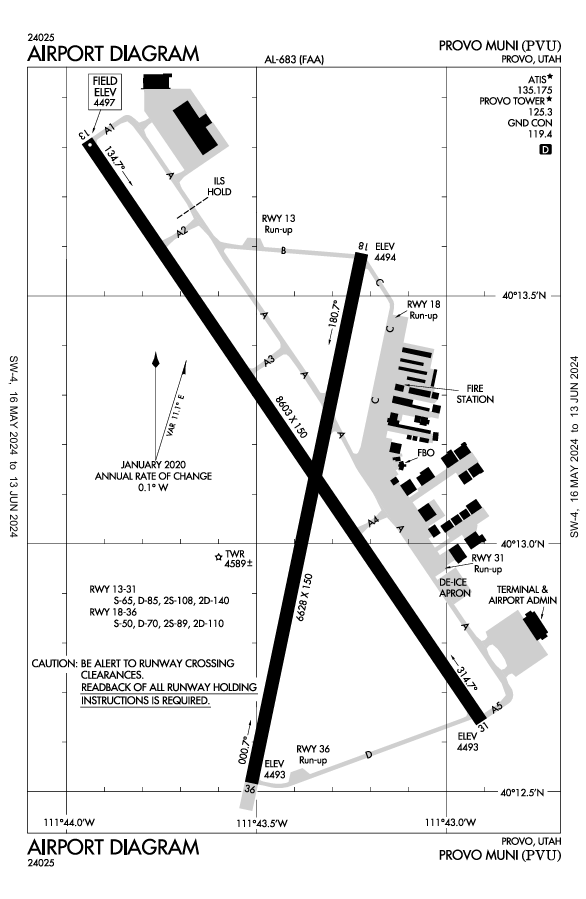

Specifically, notice that magnetic north deviates from the geographic north by 11.1 degrees east, resulting in the shorter runway (runway 36) having a direction of "North", that doesn't align with the geographic north indicated by the background latitude and longitude lines.  There are, essentially, two different basis being used in this diagram: the geographic basis and the magnetic basis. Both basis vectors are serve important roles.  First, the magnetic basis can be observed using a magnetic compass and allows for two nearby individuals to find the same direction  (e.g., "this way is north") using a simple device (e.g., a floating magnet) even though they can't see each other.  However, over time Earth's magnetic field shifts and thus directions vary over time.  This image states that every year magnetic north rotates westward by 0.1 degrees.  That may not seem like a lot, but landowners want to be able to precisely locate the boundaries of their land for decades and a constantly changing basis would make this difficult.  For this reason, we use the static geographic basis (i.e., latitude & longitude) in our maps.  However we now encounter the challenge of converting between the two basis, for example, can we determine the angle of runway 36 in the geographic basis?

clear

$$from\_basis = \left[\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right]$$

close all

$$to\_basis = \left[\begin{array}{cc} 1 & 3\\ 4 & 1 \end{array}\right]$$

We begin by defining the two basis, using $\mathit{\mathbf{G}}$ for the geographic basis and $\mathit{\mathbf{M}}$for the magnetic basis.  Note that since we normally say directions in a North/South then East/West manner (e.g., *"it's a 100-mile drive north-east of here..."*) we will use northerly directions as our first basis vector and then easterly directions as the second.  This is in contrast with the typical standard basis vectors which typically are "x, then y".

E = sym( [ [1; 0], [0; 1] ] )

$$from\_coeffs = \left[\begin{array}{c} 2\\ 5 \end{array}\right]$$

G = sym( [ [0; 1], [1; 0] ] )

$$from\_vector = \left[\begin{array}{c} 2\\ 5 \end{array}\right]$$

deviation_angle = deg2rad( sym( 11.1 ) );

$$to\_coeffs = \left[\begin{array}{c} \frac{13}{11}\\ \frac{3}{11} \end{array}\right]$$

$$T = \left[\begin{array}{cc} -\frac{1}{11} & \frac{3}{11}\\ \frac{4}{11} & -\frac{1}{11} \end{array}\right]$$

M = sym( [ [sin(deviation_angle); cos(deviation_angle)], [sin(deviation_angle + pi/2); cos(deviation_angle + pi/2)] ])

$$to\_vector = \left[\begin{array}{c} 2\\ 5 \end{array}\right]$$

double( M )

Then we populate the coefficient vector for the runway in the magnetic basis:

runway_angle = deg2rad( sym( 0.7 ) );
m = [ cos( runway_angle ); sin( runway_angle ) ]

Next we compute the $\mathit{\mathbf{D}}$ and $\mathit{\mathbf{C}}$matrices

for a = 1 : 2
    for b = 1 : 2
        D(a,b) = transpose( G(:,a) ) * G(:,b);

$$f = -x^{4}+4\,x^{2}+x-1$$

        C(a,b) = transpose( G(:,a) ) * M(:,b);

degree = 4

    end

$$m\_coeff = \left[\begin{array}{c} -1\\ 1\\ 4\\ 0\\ -1 \end{array}\right]$$

end

$$M = \left[\begin{array}{c} 1\\ x\\ x^{2}\\ x^{3}\\ x^{4} \end{array}\right]$$

display( D )
display( C )

Now we can compute the change of basis operator ${\mathit{\mathbf{T}}}_{\mathit{\mathbf{M}}\to \mathit{\mathbf{G}}}$:

T_MG = D \ C

Which we can now use to transform any vector from the magnetic basis to the geographic basis, including the orientation of the runway:

runway_vector = T_MG * m

$$T\_ML = \left[\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 1 & \frac{1}{4} & \frac{1}{16} & \frac{1}{64} & \frac{1}{256}\\ 1 & \frac{1}{2} & \frac{1}{4} & \frac{1}{8} & \frac{1}{16}\\ 1 & \frac{3}{4} & \frac{9}{16} & \frac{27}{64} & \frac{81}{256}\\ 1 & 1 & 1 & 1 & 1 \end{array}\right]$$

runway_vector = double( runway_vector )

$$l\_coeff = \left[\begin{array}{c} -1\\ -\frac{129}{256}\\ \frac{7}{16}\\ \frac{431}{256}\\ 3 \end{array}\right]$$

runway_orientation = rad2deg( atan( runway_vector(2) / runway_vector(1) ) )

Which allows us to say that the runway is oriented 11.8 degrees east of geographical north.  Now, this 

function [to_coeffs, T] = VectorChangeOfBasis( from_basis, to_basis, from_coeffs )
for a = 1 : size( from_basis, 1 )
    for b = 1 : size( from_basis, 2 )
        D(a,b) = transpose( to_basis(:,a) ) * to_basis(:,b);
        C(a,b) = transpose( to_basis(:,a) ) * from_basis(:,b);
    end
end
R = D \ C;

$$l\_coeff = \left[\begin{array}{c} -1\\ -\frac{129}{256}\\ \frac{7}{16}\\ \frac{431}{256}\\ 3 \end{array}\right]$$

to_coeffs = R * from_coeffs;

$$b\_coeff = \left[\begin{array}{c} -1\\ -\frac{3}{4}\\ \frac{1}{6}\\ \frac{7}{4}\\ 3 \end{array}\right]$$

end

$$p\_coeff = \left[\begin{array}{c} \frac{19}{30}\\ \frac{21}{10}\\ \frac{8}{21}\\ -\frac{1}{10}\\ -\frac{1}{70} \end{array}\right]$$

clear

$$t\_coeff = \left[\begin{array}{c} \frac{93}{128}\\ \frac{33}{16}\\ \frac{9}{32}\\ -\frac{1}{16}\\ -\frac{1}{128} \end{array}\right]$$

from_basis = sym( [ [1; 0], [0; 1] ] )

$$lp\_coeff = \left[\begin{array}{c} -1.0\\ -0.6341\\ 0.4375\\ 1.935\\ 3.0 \end{array}\right]$$

to_basis = sym( [ [1; 4], [3; 1] ] )

$$lt\_coeff = \left[\begin{array}{c} -1.0\\ -0.6644\\ 0.4375\\ 1.999\\ 3.0 \end{array}\right]$$

from_coeffs = sym( [2; 5] )
from_vector = from_basis * from_coeffs
[to_coeffs, R] = VectorChangeOfBasis( from_basis, to_basis, from_coeffs )
to_vector = to_basis * to_coeffs

#### Polynomial change of basis

As you may have guessed, given that polynomials form a vector space, we can also perform change of basis on polynomials.

clear
x = sym( "x", "real" );
domain = [0, 1];

f = -1*x^4 + 4*x^2 + 1*x^1 - 1*x^0
degree = polynomialDegree( f )
m_coeff = transpose( fliplr( coeffs( f, "All" ) ) )
M = MonomialBasis( degree, x, domain )
L = LagrangeBasis( degree, x, domain );

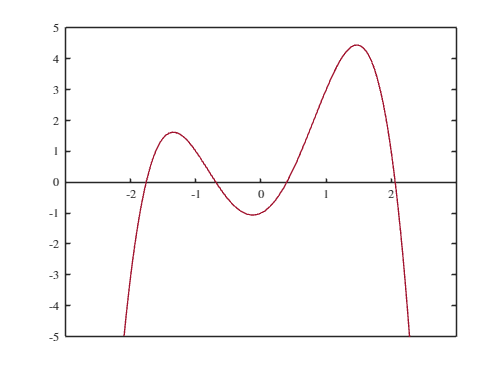

for a = 1 : degree + 1

    for b = 1 : degree + 1
        D(a,b) = int( L(a) * L(b), domain );
        C(a,b) = int( L(a) * M(b), domain );
    end
end
R_ML = D \ C
l_coeff = R_ML * m_coeff

Recognize that with this calculation we can now write this polynomial in one of three ways:

- 
$$p\left(x\right)=-x^4 +3x^2 +x-1$$


- 
$$p\left(x\right)=-1M_4^4 +0\;M_3^4 +3M_2^4 +1M_1^4 -1M_0^4$$


- 
$$p\left(x\right)=3L_4^4 -\frac{431}{256}L_3^4 +\frac{7}{16}L_2^4 -\frac{129}{256}L_1^4 -1L_0^4$$


To aid us in exploring further, let's write a function to perform the polynomial change of basis.  Note that due to Matlab's vectorization and implicit expansion syntax we can condense the looping structure from:

to

function [ to_coeffs, T, D, C ] = PolynomialChangeOfBasis( from_basis, to_basis, from_coeffs, domain )
D = int( to_basis .* transpose( to_basis ), domain );
C = int( to_basis .* transpose( from_basis ), domain );
T = D \ C;

$$f = \sin\left(x\right)$$

to_coeffs = T * from_coeffs;

$$g = \cos\left(x\right)$$

end

$$h = \sin\left(x\right)-\cos\left(x\right)$$

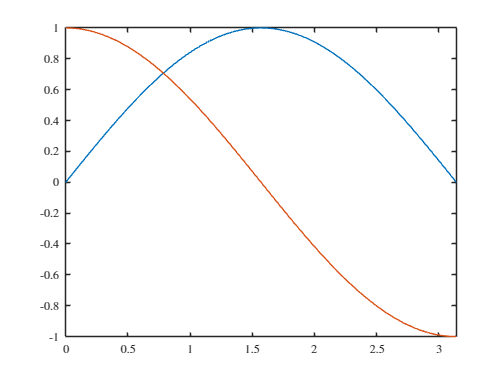

L = LagrangeBasis( degree, x, domain );
B = BernsteinBasis( degree, x, domain );
P = LegendreBasis( degree, x, domain );
R = ChebyshevBasis( degree, x, domain );

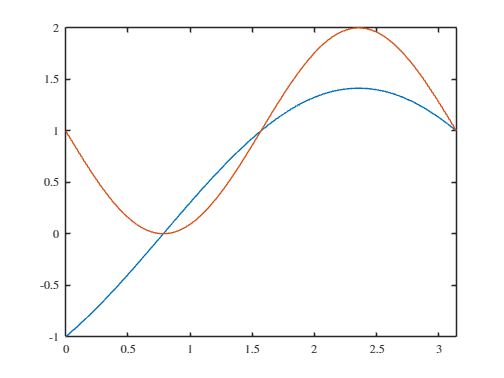

LP = LagrangeLegendreBasis( degree, x, domain );
LT = LagrangeChebyshevBasis( degree, x, domain );

l_coeff = PolynomialChangeOfBasis( M, L, m_coeff, domain )
b_coeff = PolynomialChangeOfBasis( M, B, m_coeff, domain )

p_coeff = PolynomialChangeOfBasis( M, P, m_coeff, domain )
t_coeff = PolynomialChangeOfBasis( M, R, m_coeff, domain )
lp_coeff = vpa( PolynomialChangeOfBasis( M, LP, m_coeff, domain ), 4 )
lt_coeff = vpa( PolynomialChangeOfBasis( M, LT, m_coeff, domain ), 4 )

figure
hold on
fplot( f, [-3 3], Color="k" )
fplot( transpose( m_coeff ) * M, [-3 3], SeriesIndex=1 )
fplot( transpose( l_coeff ) * L, [-3 3], SeriesIndex=2 )
fplot( transpose( b_coeff ) * B, [-3 3], SeriesIndex=3 )
fplot( transpose( p_coeff ) * P, [-3 3], SeriesIndex=4 )
fplot( transpose( t_coeff ) * R, [-3 3], SeriesIndex=5 )
fplot( transpose( lp_coeff ) * LP, [-3 3], SeriesIndex=6 )
fplot( transpose( lt_coeff ) * LT, [-3 3], SeriesIndex=7 )
ax = gca;
ax.YLim = [-5 5];
ax.XAxisLocation = "origin";


## Integration

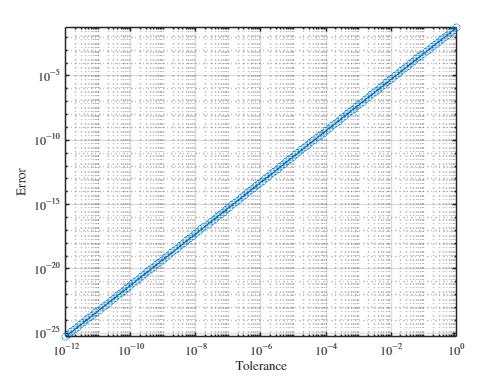

clear

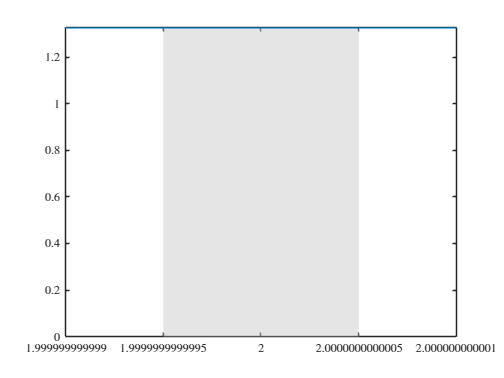

close all

x = sym( "x" );
a = 2; sym( pi / 2 );
deriv = 1;

f = sin( x )
g = cos( x )
h = f - g

figure
hold on
fplot( f, [0 pi] )
fplot( g, [0 pi] )

figure
hold on
fplot( h, [0 pi] )
fplot( h*h, [0 pi] )

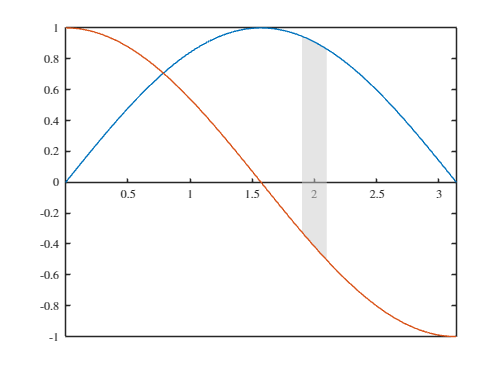


tol = sym( logspace( -12, 0, 130 ) );
penalty = 1./tol;
for ii = 1 : length( tol )
    exact(ii,1) = subs( h, x, a );
    int_domain = [a - tol(ii) / 2, a + tol(ii) / 2];
    int( h, int_domain );
    approx(ii,1) = penalty(ii) * int( h, int_domain );
    error(ii,1) = exact(ii) - approx(ii);
end


figure
plot( tol, error, Marker="o" )
ax = gca;
ax.XScale = "log";
ax.YScale = "log";
ax.XGrid = "on";
ax.YGrid = "on";
xlabel( "Tolerance" )
ylabel( "Error" )

figure
for ii = 1 : length( tol )
    xd = transpose( linspace( a - tol(end-(ii-1))/2, a + tol(end-(ii-1))/2, 1e3 ) );
    yhigh = double( subs( h, x, xd ) );
    ylow = zeros( size( yhigh ) );
    if ii == 1
        hold on
        plt{1} = fill( [xd; flipud( xd )], [yhigh; flipud( ylow )], [0.8 0.8 0.8], LineStyle="none", FaceAlpha=0.5 );
        plt{2} = fplot( h, [0 pi] );
        ax = gca;
        ax.XAxisLocation = "origin";
    else
        plt{1}.XData = double( [xd; flipud( xd )] );
        plt{1}.YData = double( [yhigh; flipud( ylow )] );
    end
    ax.XLim = double( [a - tol(end-(ii-1)), a + tol(end-(ii-1))] );
    drawnow
end

figure
hold on
xd = transpose( linspace( a - 0.1, a + 0.1, 1e3 ) );
yhigh = double( subs( max( f, g ), x, xd ) );
ylow = double( subs( min( f, g ), x, xd ) );
fill( [xd; flipud( xd )], [yhigh; flipud( ylow )], [0.8 0.8 0.8], LineStyle="none", FaceAlpha=0.5 )
fplot( f, [0 pi] )
fplot( g, [0 pi] )
ax = gca;
ax.XAxisLocation = "origin";

function scaled_arrow( ax, arrow_center, arrow_slope, arrow_length )
cx = arrow_center(1);
cy = arrow_center(2);
[coord_x, coord_y] = coord2norm( ax, [cx - ( arrow_length / 2 ) * cos( tan( arrow_slope ) ), cx + ( arrow_length / 2 ) * cos( tan( arrow_slope ) )], [cy - ( arrow_length / 2 ) * sin( tan( arrow_slope ) ), cy + ( arrow_length / 2 ) * sin( tan( arrow_slope ) )] );
annotation( "textarrow", coord_x, coord_y )
end